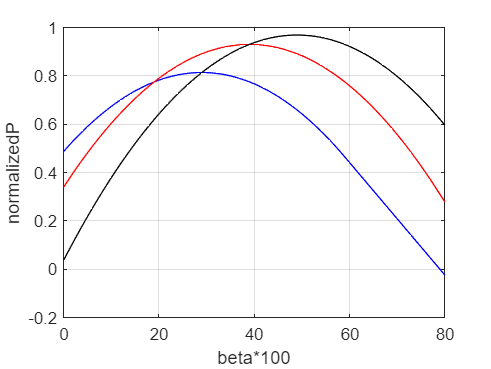

% Vbat=50;
% Vdc=800;
% f=100e3;
% Lk=100e-6;
% n=4;功率归一化，所以以上参数暂时注释
clearvars

Lk=1;
n=189;%傅里叶展开次数，奇数次展开
m=81;%迭代式中移相比=m/100，m表示占比的整数值
Po=zeros(n);
po=Po(1:n,1:m); 
D=0.3;%单独设定占空比，对应一条曲线
for i=1:2:n
    for beta=1:m
            po(i+2,beta)=po(i,beta)+1/i^3/Lk*cos(i*(0.5-D)*pi)...
            *sin(i*(beta*pi/100+(0.5-D)*pi));
    end
end

%x=0.01:0.01:0.5;
x=0:m-1;
% y1=Po(:,0)
% plot(x,y1)
% hold on
y1=po(n,:);
plot(x,y1,'blue')
xlabel('beta*100') %设置横坐标轴
ylabel('normalizedP') %设置纵坐标轴
hold on
grid on
% y3=po(n,:,2);%D=0.5
% plot(x,y3,'red')
% hold on
% y4=po(n,:,3);%D=0.75
% plot(x,y4,'black')
% hold on
D=0.4;
for i=1:2:n
    for beta=1:m
            po(i+2,beta)=po(i,beta)+1/i^3/Lk*cos(i*(0.5-D)*pi)...
            *sin(i*(beta*pi/100+(0.5-D)*pi));
    end
end
y2=po(n,:);
plot(x,y2,'red')
% xlabel('beta*100') %设置横坐标轴
% ylabel('normalizedP') %设置纵坐标轴
hold on

D=0.5;
for i=1:2:n
    for beta=1:m
            po(i+2,beta)=po(i,beta)+1/i^3/Lk*cos(i*(0.5-D)*pi)...
            *sin(i*(beta*pi/100+(0.5-D)*pi));
    end
end
y3=po(n,:);
plot(x,y3,'black')
% xlabel('beta*100') %设置横坐标轴
% ylabel('normalizedP') %设置纵坐标轴
hold on